# Editing bathymetry files

This guide explains how to use Matlab to edit NewDepomod bathymetry property files

## Initialise the bathymetry object

Get the bathymetry object, as shown in previous guides.

projectDir = 'C:\newdepomod_projects\bay_of_fish';
project    = NewDepomod.Project.create(projectDir);
bathy      = project.bathymetry  

bathy =   BathymetryFile with properties:

    GridgenBathymetryFile: [0×0 AutoDepomod.BathymetryFile]
        GridgenDomainFile: [0×0 AutoDepomod.DomainFile]
                     data: [79×79 double]
                     path: 'C:\newdepomod_projects\bay_of_fish\depomod\bathymetry\bay_of_fish.depomodbathymetryproperties'
                   Domain: [1×1 struct]
          endOfDataMarker: 'endOfDataMarker'
        startOfDataMarker: 'startOfDataMarker'

## Edit the domain bounds

First let's look at the domain bounds

bathy.Domain.spatial

ans = struct with fields:
    reference: [1×1 struct]
         minX: '349340'
         maxX: '351340'
         minY: '1067960'
         maxY: '1069960'

We can access inidivual values like this,

bathy.Domain.spatial.minX

ans = '349340'

To edit we simply set it "=" to a new value. However, these properties files require a *string *value for the value to be written successfully back to file, so we use `num2str()` (we could simply wrap the number in single quotes).

Let's shift the whole domain northwards by 1000 m.

bathy.Domain.spatial.minY = num2str(1068960);
bathy.Domain.spatial.maxY = num2str(1070960);

This requirement to supply strings rather than numbers is awkward and should be improved in the library eventually.

Let's check the values to make sure they've changed

bathy.Domain.spatial

ans = struct with fields:
    reference: [1×1 struct]
         minX: '349340'
         maxX: '351340'
         minY: '1068960'
         maxY: '1070960'

## Edit the grid resolution

The grid resolution, described in these properties 

bathy.Domain.data.numberOfElementsX

ans = '79'

bathy.Domain.data.numberOfElementsY

ans = '79'

can be edited in the same way. Let's just change them to 80 x 80.

bathy.Domain.data.numberOfElementsX = num2str(80);
bathy.Domain.data.numberOfElementsY = num2str(80);

Again, let's check.

bathy.Domain.data

ans = struct with fields:
        elementFormat: 'csvRegularGrid'
    numberOfElementsX: '80'
    numberOfElementsY: '80'

## Edit the water depth data

Now we've changed the domain resolution, we need to make sure that the water depth data is consistent with this arrangement. Specifically, we need the matrix of water depth values to be sized 80 x 80. Currently it is

size(bathy.data)

ans =     79    79


which is not acceptable. This table can simply be overwritten using any valid Matlab operations and manipulations. In a real modelling scenario it needs to be populated with accurate bathymetry and land data for which there is no general solution. Here we'll just set a straight coastline on the west and an eastward sloping seabed.

Initialise a new container with the correct dimensions (80 x 80)

newBathyData = zeros(80,80);

Set the first few columns as land (value = +10)

newBathyData(:,1:5) = 10

newBathyData =     10    10    10    10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    10    10    10    10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    10    10    10    10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    10    10    10    10    10     0     0     0     0     0     0     0     0    

Iterate through the existing columns

for c = 6:80
    % increase depth by a meter for every iteration
    newBathyData(:,c) = -10 - c;
end

Assign the new data to the `BathymetryFile` object

bathy.data = newBathyData

bathy =   BathymetryFile with properties:

    GridgenBathymetryFile: [0×0 AutoDepomod.BathymetryFile]
        GridgenDomainFile: [0×0 AutoDepomod.DomainFile]
                     data: [80×80 double]
                     path: 'C:\newdepomod_projects\bay_of_fish\depomod\bathymetry\bay_of_fish.depomodbathymetryproperties'
                   Domain: [1×1 struct]
          endOfDataMarker: 'endOfDataMarker'
        startOfDataMarker: 'startOfDataMarker'

Now, let's take a look

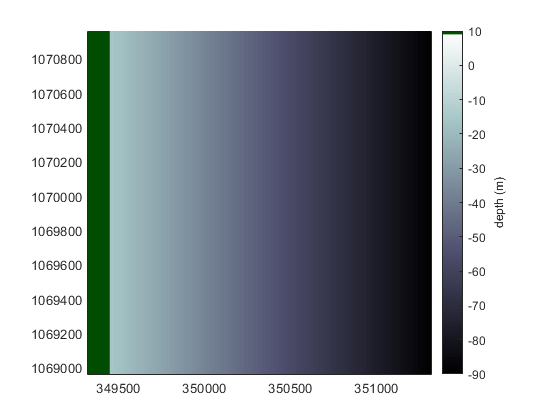

figure; bathy.plot

## Saving the altered information back to file

All of the changes can be easily written back to the original file using

bathy.toFile

If the changes should be saved to a different file (perhaps to avoid writing over a useful bathymetry representation) then the required file path can be passed in as an option.

bathy.toFile('path\to\file.depomodbathymetryproperties')

Note that when writing to arbitrary files, the correct file extension is not required - this is just a plain text file. The correct file extension (and file location) is required for using in the NewDepomod software in most cases, however.